# Autoencoders for Wireless Communications

k = 8;    % number of input bits
M = 2^k;  % number of possible input symbols
n = 4;    % number of channel uses
rng(42);

% Feature Extractor
feLayers = [
    fullyConnectedLayer(256, 'Name', 'fe_initial')
    reluLayer("Name","relu_f1")
    fullyConnectedLayer(8, 'Name', 'feature_extractor')
];
% Phase Estimator
peLayers = [
    fullyConnectedLayer(256, 'Name', 'pe_initial')
    reluLayer("Name","relu_p1")
    fullyConnectedLayer(128, 'Name', 'phase_estimator_dense1')
    reluLayer("Name","relu_p2")
    fullyConnectedLayer(2, 'Name', 'phase_estimator')
    pe_2Layer("Name","pe_2")
];

% Offset Estimator
oeLayers = [
    fullyConnectedLayer(256, 'Name', 'oe_initial')
    reluLayer("Name","relu_o1")
    fullyConnectedLayer(128, 'Name', 'oe_dense1')
    reluLayer("Name","relu_o2")
    fullyConnectedLayer(32, 'Name', 'oe_dense2')
    reluLayer("Name","relu_o3")
    fullyConnectedLayer(16, 'Name', 'offset_estimator')
    softmaxLayer("Name","softmax_oe")
];

SDLayer_ = [SDLayer("Name","SD_mini_Layer")];
SDLayerGraph = layerGraph(SDLayer_);

% Define the input layer 
inputLayer = sequenceInputLayer(1, 'Name', 'Input', 'Normalization', 'none'); 
% Define the initial layers 
initialLayers = [ 
    inputLayer
    embeddingLayer2(M,M,"Name","embeddingLayer")
    %fullyConnectedLayer(256, 'Name', 'Embedding') 
    reshapeLayer(1, 256, 'Name', 'reshape_1') 
    convolution1dLayer(1, 256, 'Name', 'Conv1D_1') 
    eluLayer 
    %layerNormalizationLayer 
    convolution1dLayer(1, 128, 'Name', 'Conv1D_2') 
    eluLayer 
    %layerNormalizationLayer 
    convolution1dLayer(1, 64, 'Name', 'Conv1D_3') 
    eluLayer 
    %layerNormalizationLayer 
    convolution1dLayer(1, 2 * n, 'Name', 'Conv1D_4') 
    layerNormalizationLayer
    helperAEWNormalizationLayer("Method", "Energy", "Name", "Normalization") 
    SlidingWindow(13, "Name", "SlidingWindow") 
    StochasticChannelv3('Name', 'StochasticChannelv3') 
    helperCustomizeNoiseLayer('Name', 'NoiseLayer') ];

% Define the remaining layers 
remainingLayers = [ 
    reshapeLayer(1, 58, 'Name', 'reshape_2')
    %layerNormalizationLayer('Name', 'layer_norm')
    convolution1dLayer(1, 64, 'Name', 'Conv1D_Dec1') 
    eluLayer 
    %layerNormalizationLayer 
    convolution1dLayer(1, 128, 'Name', 'Conv1D_Dec2') 
    eluLayer 
    %layerNormalizationLayer 
    convolution1dLayer(1, 256, 'Name', 'Conv1D_Dec3') 
    eluLayer 
    %layerNormalizationLayer
    reshapeLayer2("Name","OutputReshaper")
    fullyConnectedLayer(M, 'Name', 'Output') 
    softmaxLayer('Name', 'Softmax') 
    classificationLayer("Name", "classoutput") ];



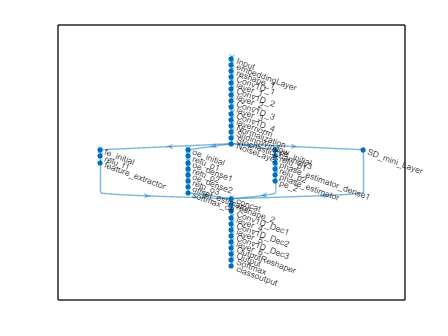

lgraph = layerGraph();

% Add initial layers 
lgraph = addLayers(lgraph, initialLayers); 

% Add submodels 
lgraph = addLayers(lgraph, feLayers); 
lgraph = addLayers(lgraph, peLayers); 
lgraph = addLayers(lgraph, oeLayers);
lgraph = addLayers(lgraph, SDLayer_);


% Add remaining layers 
lgraph = addLayers(lgraph, remainingLayers); 

% Connect the layers 
lgraph = connectLayers(lgraph, 'NoiseLayer', 'fe_initial'); 
lgraph = connectLayers(lgraph, 'NoiseLayer', 'pe_initial'); 
lgraph = connectLayers(lgraph, 'NoiseLayer', 'oe_initial'); 
lgraph = connectLayers(lgraph, 'NoiseLayer', 'SD_mini_Layer'); 

% Concatenate the outputs from the submodels 
concatLayer = concatenationLayer(1, 4, 'Name', 'concat'); 
lgraph = addLayers(lgraph, concatLayer);

lgraph = connectLayers(lgraph, 'SD_mini_Layer', 'concat/in1'); 
lgraph = connectLayers(lgraph, 'pe_2', 'concat/in2'); 
lgraph = connectLayers(lgraph, 'feature_extractor', 'concat/in3'); 
lgraph = connectLayers(lgraph, 'softmax_oe', 'concat/in4'); 
% Connect the concatenated output to the Conv1D_Dec1 layer 
lgraph = connectLayers(lgraph, 'concat', 'reshape_2'); 
plot(lgraph)

% Create input data for 100 sequences, each with a single time step
numSequences = 12800;
% Define categories (assuming 0-255 are the possible categories)
categories = 0:255;

% Create training data for 6400 sequences
inputTData = cell(1, numSequences);
TL = cell(1, numSequences);  % Cell array for training labels

for i = 1:numSequences
    % Each sequence is a single value (1 time step, 1 feature)
    inputTData{i} = randi([0, 255], 1, 1);  % Random integer between 0-255
    % Convert to categorical label (since it's a sequence-to-sequence task, use a sequence of categories)
    TL{i} = categorical(inputTData{i}, categories);  % Single categorical value per sequence
end

numSequences = 6400;
% Create validation data (same structure as training data)
inputVData = cell(1, numSequences);
VL = cell(1, numSequences);  % Cell array for validation labels

for i = 1:numSequences
    % Each sequence is a single value (1 time step, 1 feature)
    inputVData{i} = randi([0, 255], 1, 1);  % Random integer between 0-255
    % Convert to categorical label for validation
    VL{i} = categorical(inputVData{i}, categories);  % Single categorical value per sequence
end

numSequences = 3200;
% Create validation data (same structure as training data)
inputTEData = cell(1, numSequences);
TEL = cell(1, numSequences);  % Cell array for validation labels

for i = 1:numSequences
    % Each sequence is a single value (1 time step, 1 feature)
    inputTEData{i} = randi([0, 255], 1, 1);  % Random integer between 0-255
    % Convert to categorical label for validation
    TEL{i} = categorical(inputTEData{i}, categories);  % Single categorical value per sequence
end

display(inputTData)

inputTData = 1×12800 cell array
  Columns 1 through 946

    {[96]}    {[149]}    {[128]}    {[168]}    {[71]}    {[30]}    {[20]}    {[49]}    {[123]}    {[60]}    {[111]}    {[7]}    {[160]}    {[224]}    {[12]}    {[55]}    {[81]}    {[73]}    {[10]}    {[27]}    {[233]}    {[182]}    {[245]}    {[112]}    {[225]}    {[209]}    {[223]}    {[10]}    {[167]}    {[145]}    {[139]}    {[129]}    {[203]}    {[247]}    {[212]}    {[222]}    {[123]}    {[176]}    {[106]}    {[92]}    {[229]}    {[231]}    {[174]}    {[214]}    {[92]}    {[111]}    {[210]}    {[101]}    {[10]}    {[90]}    {[101]}    {[39]}    {[88]}    {[239]}    {[219]}    {[114]}    {[181]}    {[38]}    {[192]}    {[121]}    {[184]}    {[164]}    {[59]}    {[213]}    {[146]}    {[200]}    {[24]}    {[157]}    {[74]}    {[220]}    {[243]}    {[14]}    {[185]}    {[26]}    {[219]}    {[31]}    {[49]}    {[64]}    {[186]}    {[74]}    {[152]}    {[146]}    {[102]}    {[138]}    {[30]}    {[224]}    {[53]}    {[225]}    {[13

display(TL)

TL = 1×12800 cell array
  Columns 1 through 946

    {[96]}    {[149]}    {[128]}    {[168]}    {[71]}    {[30]}    {[20]}    {[49]}    {[123]}    {[60]}    {[111]}    {[7]}    {[160]}    {[224]}    {[12]}    {[55]}    {[81]}    {[73]}    {[10]}    {[27]}    {[233]}    {[182]}    {[245]}    {[112]}    {[225]}    {[209]}    {[223]}    {[10]}    {[167]}    {[145]}    {[139]}    {[129]}    {[203]}    {[247]}    {[212]}    {[222]}    {[123]}    {[176]}    {[106]}    {[92]}    {[229]}    {[231]}    {[174]}    {[214]}    {[92]}    {[111]}    {[210]}    {[101]}    {[10]}    {[90]}    {[101]}    {[39]}    {[88]}    {[239]}    {[219]}    {[114]}    {[181]}    {[38]}    {[192]}    {[121]}    {[184]}    {[164]}    {[59]}    {[213]}    {[146]}    {[200]}    {[24]}    {[157]}    {[74]}    {[220]}    {[243]}    {[14]}    {[185]}    {[26]}    {[219]}    {[31]}    {[49]}    {[64]}    {[186]}    {[74]}    {[152]}    {[146]}    {[102]}    {[138]}    {[30]}    {[224]}    {[53]}    {[225]}    {[132]}    {

% Training options

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.0005, ...
    'SquaredGradientDecayFactor', 0.999, ...
    'GradientDecayFactor', 0.9, ... 
    'Epsilon', 1e-07, ... 
    "GradientThreshold",1, ...
    'MaxEpochs', 100, ...
    "SequenceLength","longest", ...
    'MiniBatchSize', 32, ...
    'LearnRateSchedule', 'piecewise', ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {inputVData, VL}, ...
    'ValidationPatience', 10, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


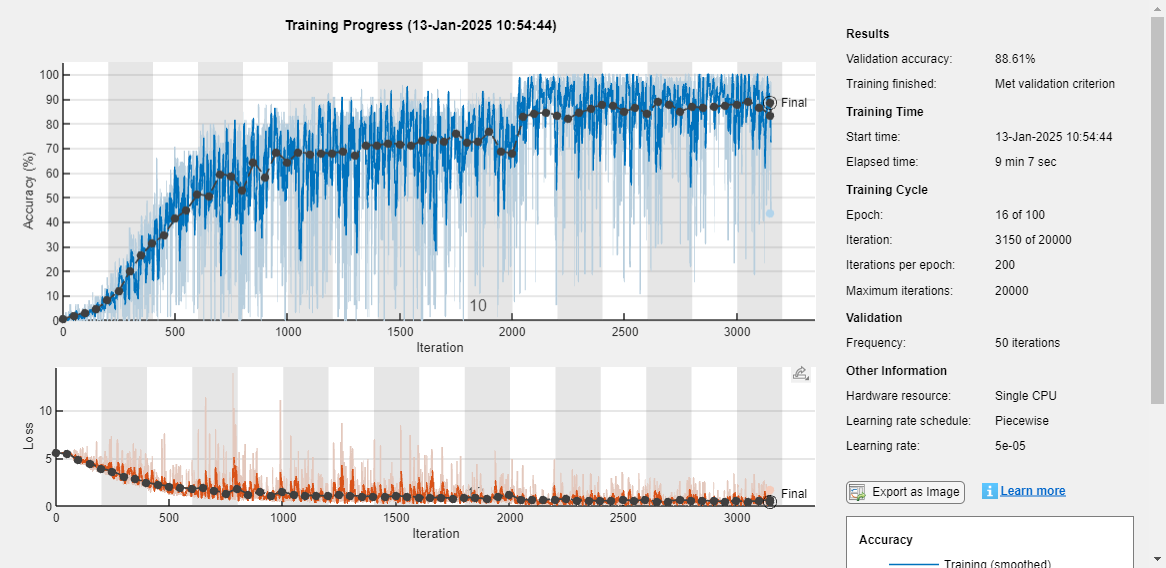

% Train the autoencoder
net = trainNetwork(inputTData, TL, lgraph, options);

predictions = predict(net, inputTEData);
display(TEL)

TEL = 1×3200 cell array
  Columns 1 through 948

    {[189]}    {[182]}    {[175]}    {[207]}    {[87]}    {[56]}    {[88]}    {[12]}    {[247]}    {[189]}    {[54]}    {[65]}    {[254]}    {[196]}    {[108]}    {[52]}    {[10]}    {[171]}    {[199]}    {[27]}    {[0]}    {[91]}    {[170]}    {[236]}    {[225]}    {[176]}    {[208]}    {[91]}    {[62]}    {[31]}    {[46]}    {[246]}    {[238]}    {[12]}    {[120]}    {[95]}    {[166]}    {[84]}    {[71]}    {[207]}    {[242]}    {[51]}    {[60]}    {[107]}    {[180]}    {[42]}    {[119]}    {[215]}    {[59]}    {[12]}    {[232]}    {[201]}    {[178]}    {[22]}    {[230]}    {[78]}    {[54]}    {[124]}    {[236]}    {[254]}    {[157]}    {[244]}    {[116]}    {[7]}    {[70]}    {[77]}    {[200]}    {[31]}    {[44]}    {[157]}    {[33]}    {[126]}    {[8]}    {[171]}    {[232]}    {[223]}    {[18]}    {[151]}    {[26]}    {[13]}    {[156]}    {[146]}    {[24]}    {[92]}    {[81]}    {[87]}    {[85]}    {[211]}    {[90]}    {[84]}    {[7]

display(predictions)

predictions = 3200×1 cell array
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}
    {256×1 single}


YPred = classify(net,inputTEData, ...
    MiniBatchSize=1024, ...
    SequenceLength="longest");
display(YPred)

YPred = 3200×1 cell array
    {[189]}
    {[182]}
    {[175]}
    {[207]}
    {[87 ]}
    {[56 ]}
    {[88 ]}
    {[12 ]}
    {[247]}
    {[189]}
    {[54 ]}
    {[65 ]}
    {[254]}
    {[196]}
    {[108]}
    {[52 ]}


y = zeros(size(YPred,1),1);
t = zeros(size(YPred,1),1);
for i =1:size(YPred,1)
    y(i) = YPred{i};
    t(i) = TEL{1}{i};
end

Error using indexing
Cell contents reference from a non-cell array object.

accuracy = sum(y == t) / numel(t);
display(accuracy)
cm = confusionmat(t, y);
accuracy = sum(diag(cm)) / sum(cm(:));
display(accuracy)
plot(cm)